Initialization

% clear all;
% close all ;
% clc;
% base_dir="..\data\"; 
% cd(base_dir);

Data Extraction

op=readtable("keypoints_colab_fixed2.csv");

transpose(op.Properties.VariableNames)

ans = 44×1 cell array
    {'frame'          }
    {'elapsed_time_s_'}
    {'neck_x'         }
    {'neck_y'         }
    {'neck_c'         }
    {'spine_hip_x'    }
    {'spine_hip_y'    }
    {'spine_hip_c'    }
    {'r_hip_x'        }
    {'r_hip_y'        }
    {'r_hip_c'        }
    {'r_knee_x'       }
    {'r_knee_y'       }
    {'r_knee_c'       }
    {'r_ankle_x'      }
    {'r_ankle_y'      }
    {'r_ankle_c'      }
    {'r_heel_x'       }
    {'r_heel_y'       }
    {'r_heel_c'       }
    {'r_bigtoe_x'     }
    {'r_bigtoe_y'     }
    {'r_bigtoe_c'     }
    {'r_smalltoe_x'   }
    {'r_smalltoe_y'   }
    {'r_smalltoe_c'   }
    {'l_hip_x'        }
    {'l_hip_y'        }
    {'l_hip_c'        }
    {'l_knee_x'       }


mocap=readtable("p1s1_mocap_2d_keypoints.csv");
transpose(mocap.Properties.VariableNames)

ans = 27×1 cell array
    {'frame'      }
    {'mocap_frame'}
    {'mocap_time' }
    {'CLAV_x'     }
    {'CLAV_y'     }
    {'LASI_x'     }
    {'LASI_y'     }
    {'RASI_x'     }
    {'RASI_y'     }
    {'LKNE_x'     }
    {'LKNE_y'     }
    {'LANK_x'     }
    {'LANK_y'     }
    {'LHEE_x'     }
    {'LHEE_y'     }
    {'LTOE_x'     }
    {'LTOE_y'     }
    {'RKNE_x'     }
    {'RKNE_y'     }
    {'RANK_x'     }
    {'RANK_y'     }
    {'RHEE_x'     }
    {'RHEE_y'     }
    {'RTOE_x'     }
    {'RTOE_y'     }
    {'SPINEHIP_x' }
    {'SPINEHIP_y' }


kf=readtable('p1s1_kf_keypoints.csv');
errors_x=[];
errors_y=[];
keypoint_names=[];
start_frame=10;
total_frame=height(op);

Graphing keypoints

Neck

keypoint_op=[op.neck_x op.neck_y];
keypoint_mocap=[mocap.CLAV_x mocap.CLAV_y];
keypoint_kf=[kf.neck_x kf.neck_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);


%plotting
%figure;
sgtitle('Neck') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")

ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

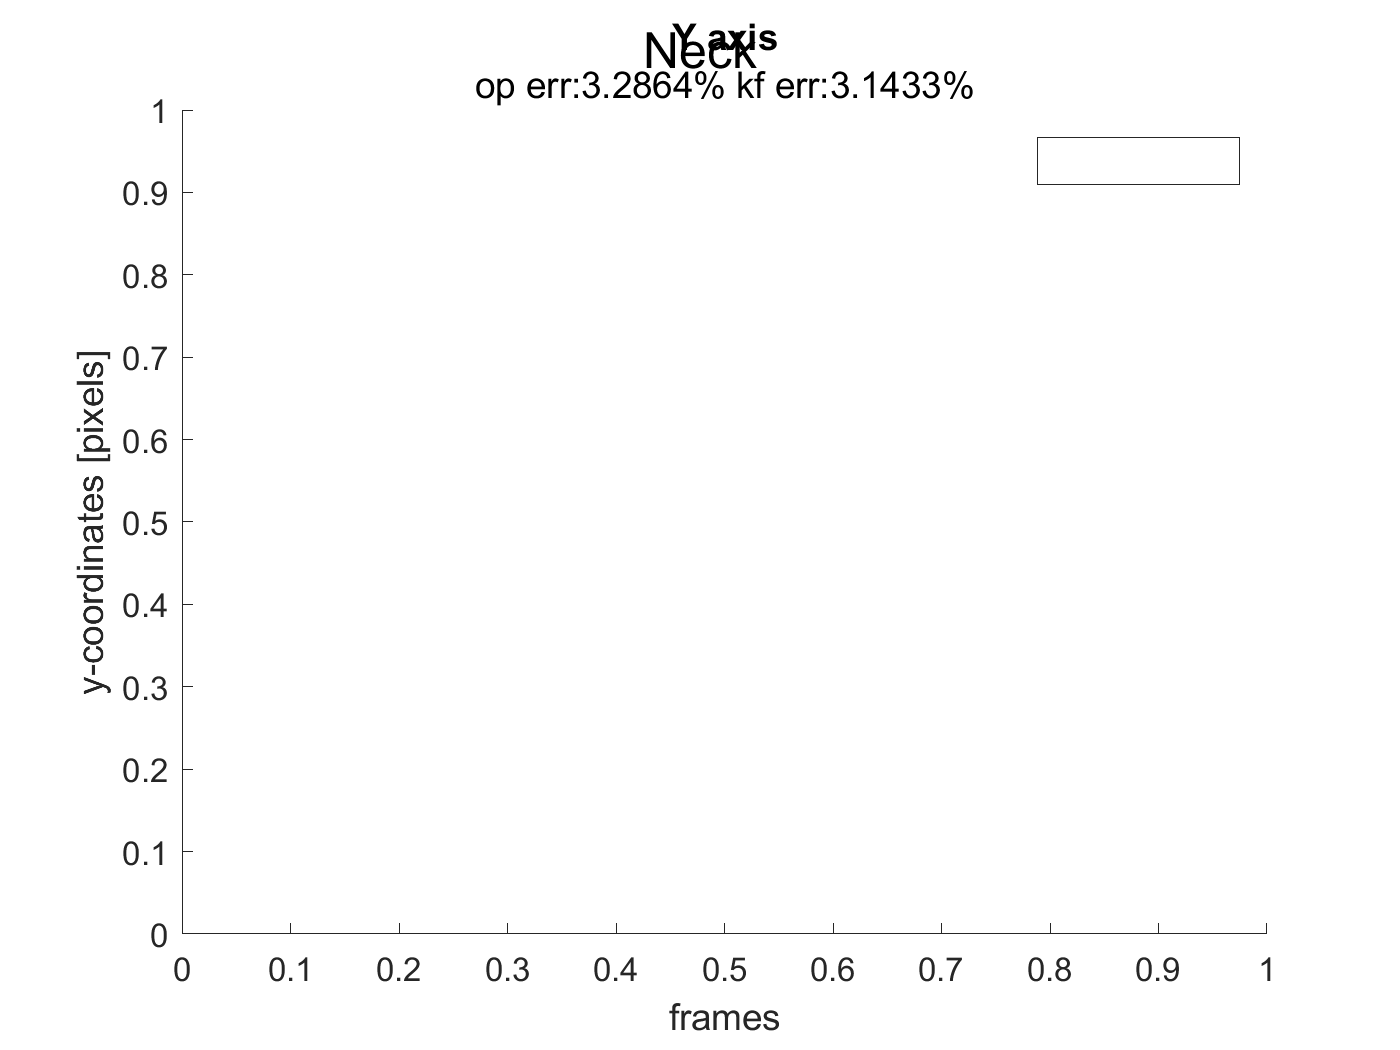

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

spine_hip

keypoint_op=[op.spine_hip_x op.spine_hip_y];
keypoint_mocap=[mocap.SPINEHIP_x mocap.SPINEHIP_y];
keypoint_kf=[kf.spine_hip_x kf.spine_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Spine hip') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
title("X axis")
subtitle("op err:"+err+"% kf err:" + err_kf +"%")

title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

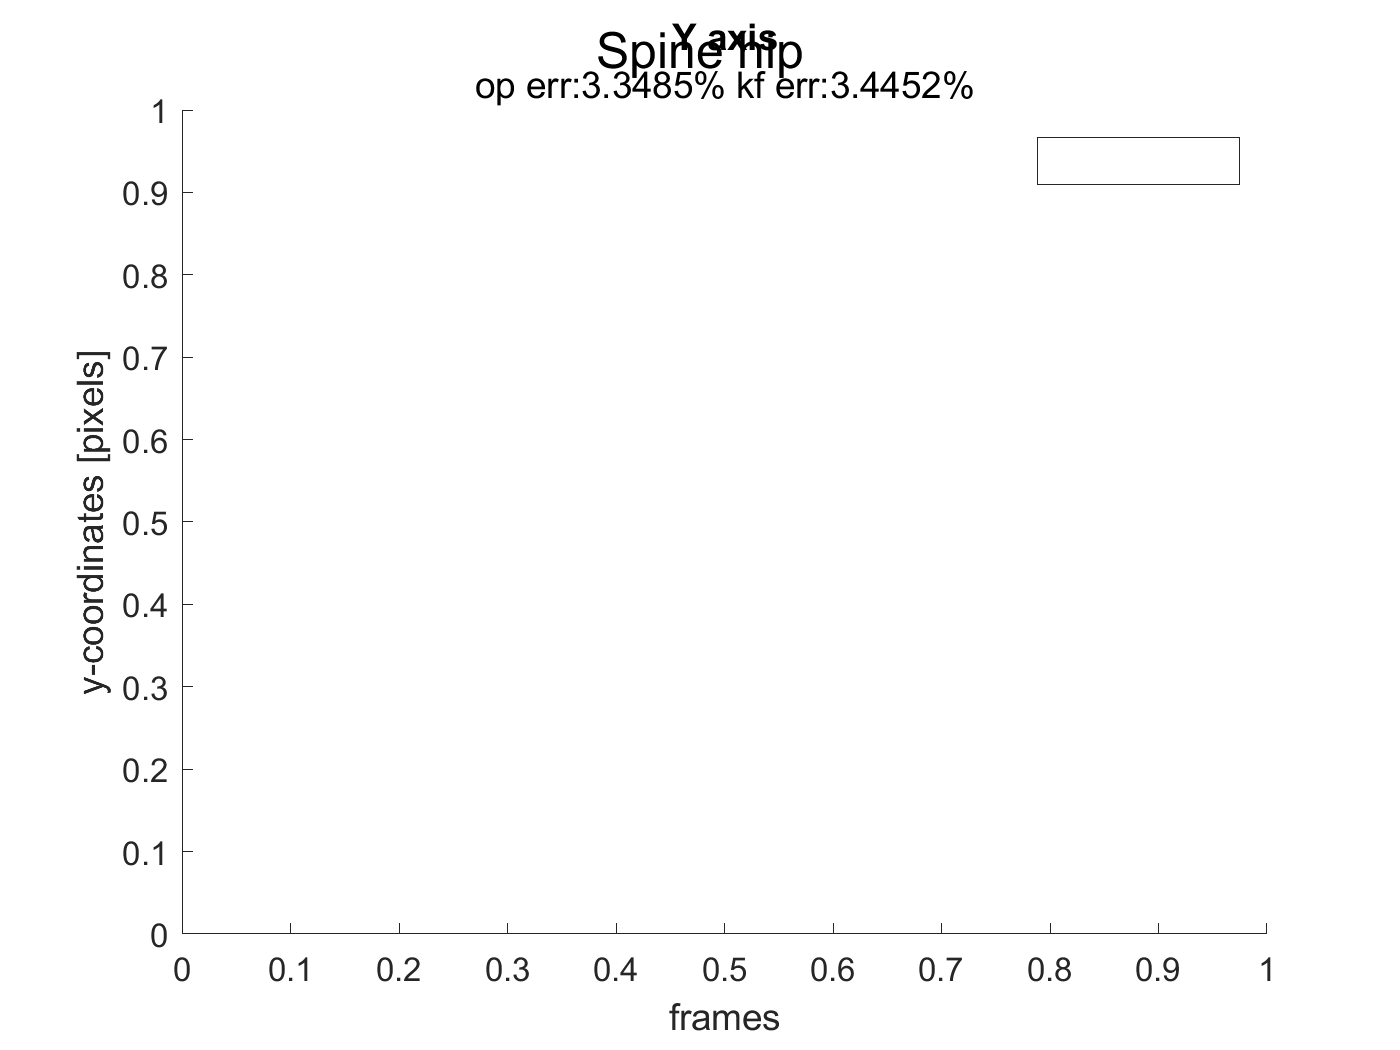

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
title("Y axis")
ylabel('y-coordinates [pixels]')
hold off;

right hip

keypoint_op=[op.r_hip_x op.r_hip_y];
keypoint_mocap=[mocap.RASI_x mocap.RASI_y];
keypoint_kf=[kf.r_hip_x kf.r_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Right Hip') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
title("X axis")
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

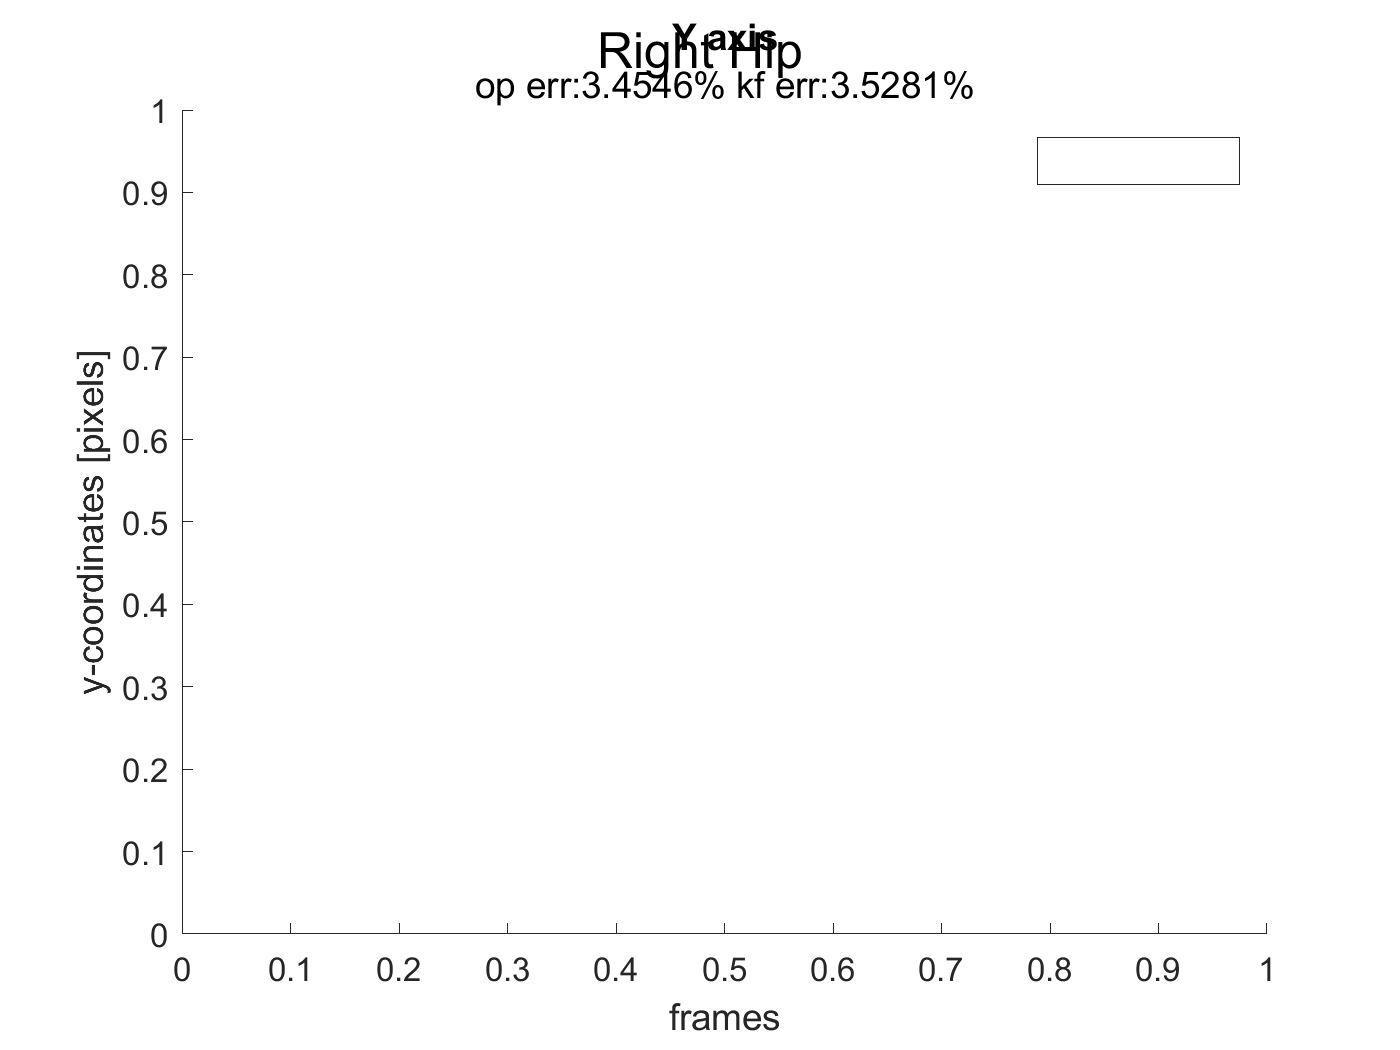

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Right Knee

keypoint_op=[op.r_knee_x op.r_knee_y];
keypoint_mocap=[mocap.RKNE_x mocap.RKNE_y];
keypoint_kf=[kf.r_knee_x kf.r_knee_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Right Knee') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

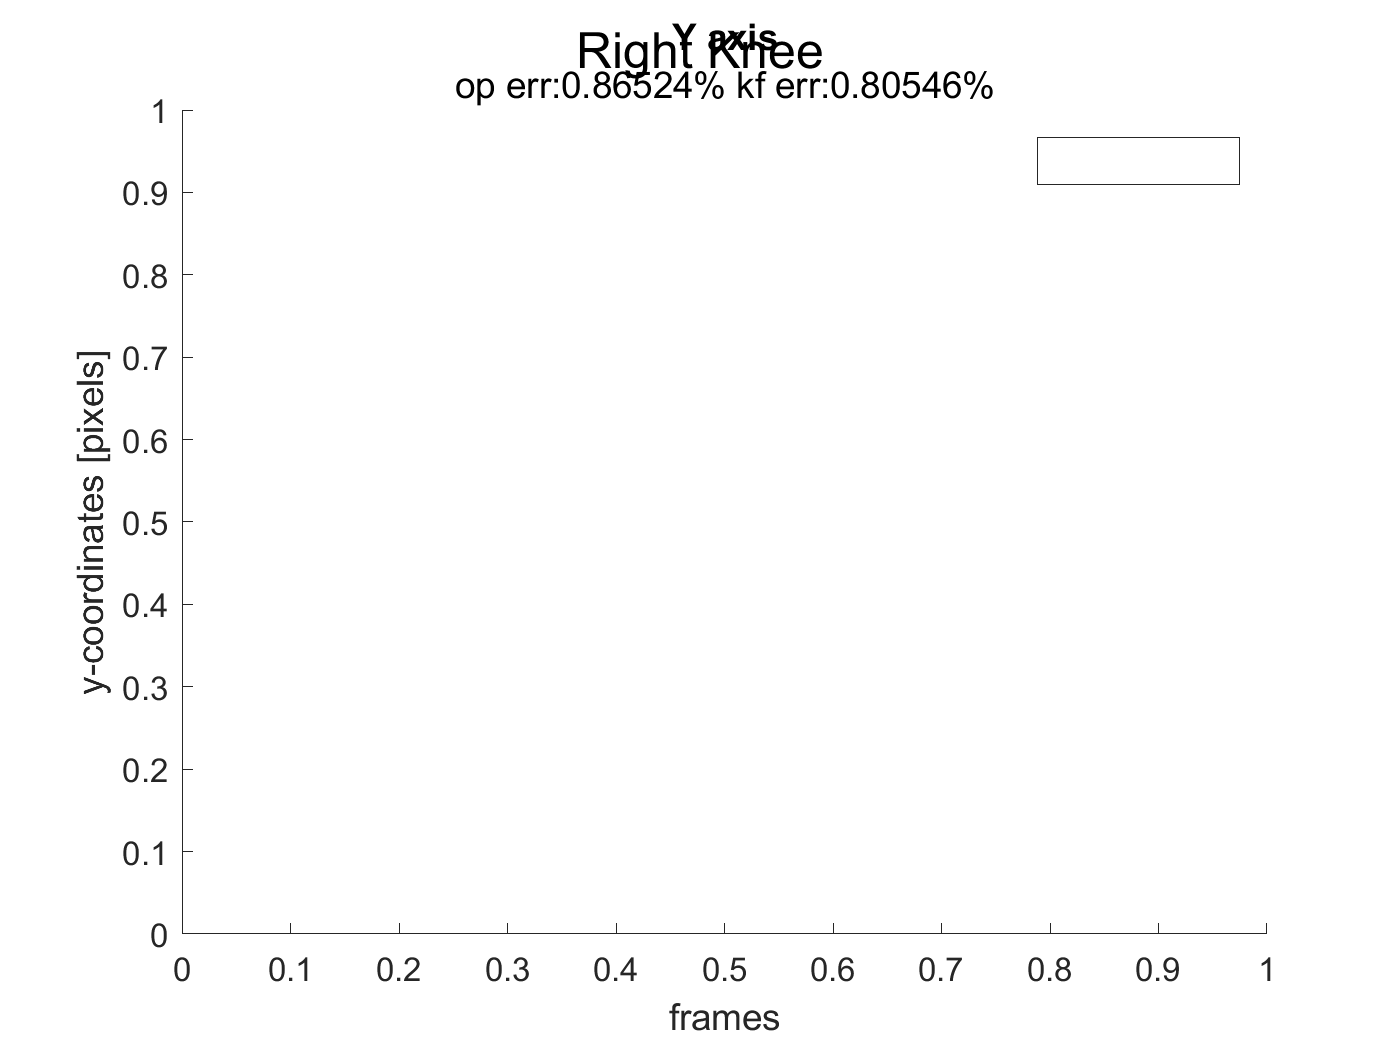

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Right ankle

keypoint_op=[op.r_ankle_x op.r_ankle_y];
keypoint_mocap=[mocap.RANK_x mocap.RANK_y];
keypoint_kf=[kf.r_ankle_x kf.r_ankle_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Right Ankle') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

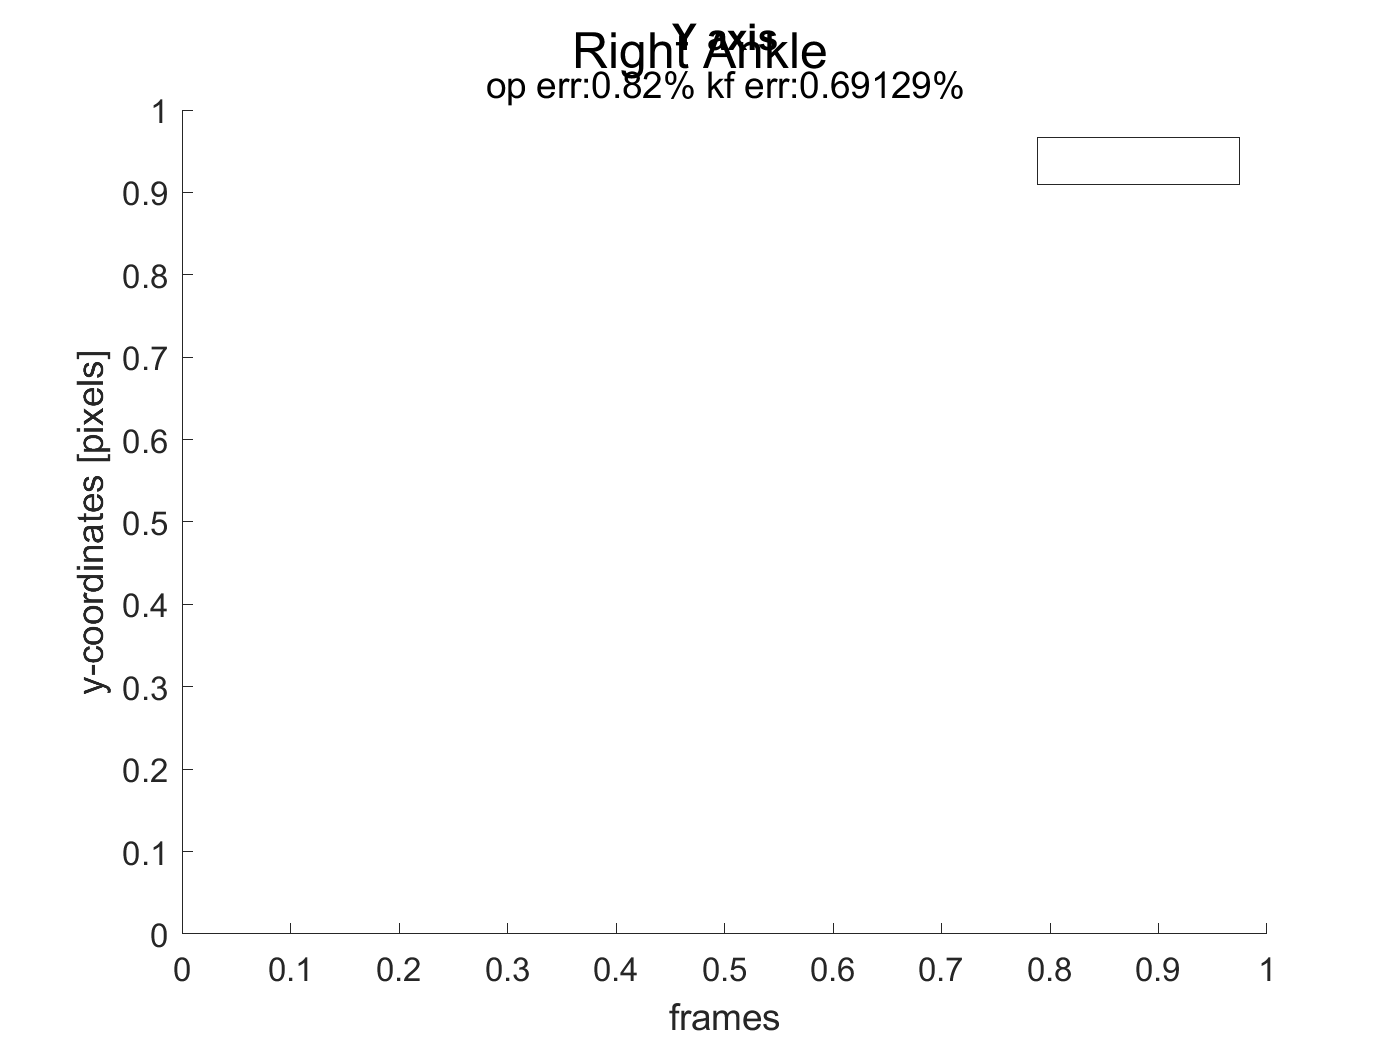

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Right heel

keypoint_op=[op.r_heel_x op.r_heel_y];
keypoint_mocap=[mocap.RHEE_x mocap.RHEE_y];
keypoint_kf=[kf.r_heel_x kf.r_heel_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Right Heel') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

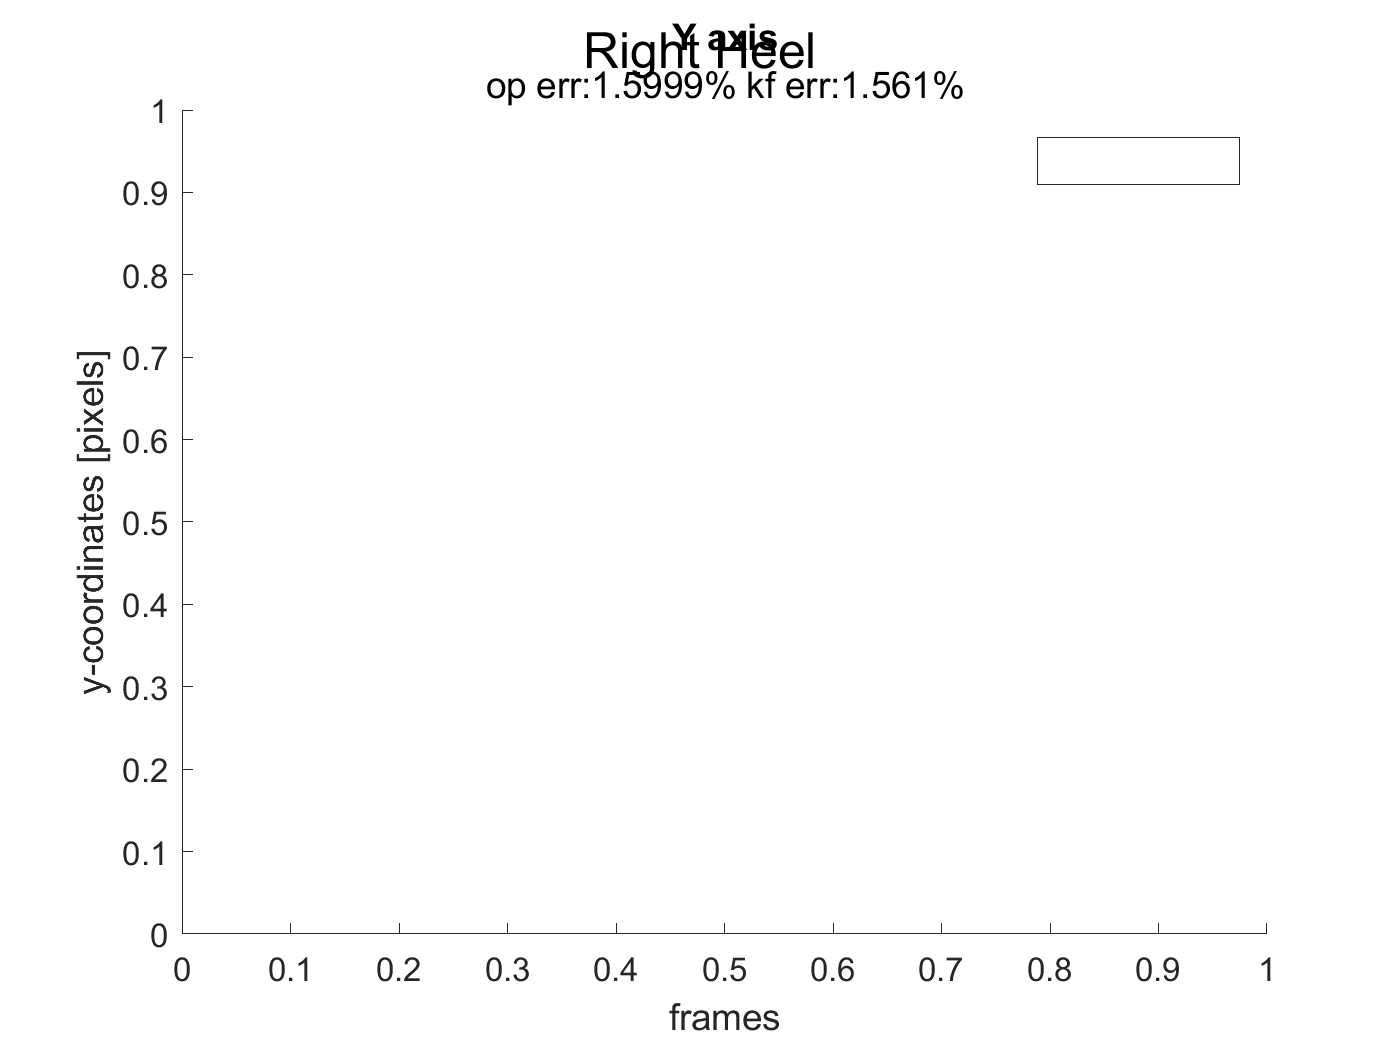

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Left hip

keypoint_op=[op.l_hip_x op.l_hip_y];
keypoint_mocap=[mocap.LASI_x mocap.LASI_y];
keypoint_kf=[kf.l_hip_x kf.l_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Left Hip') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

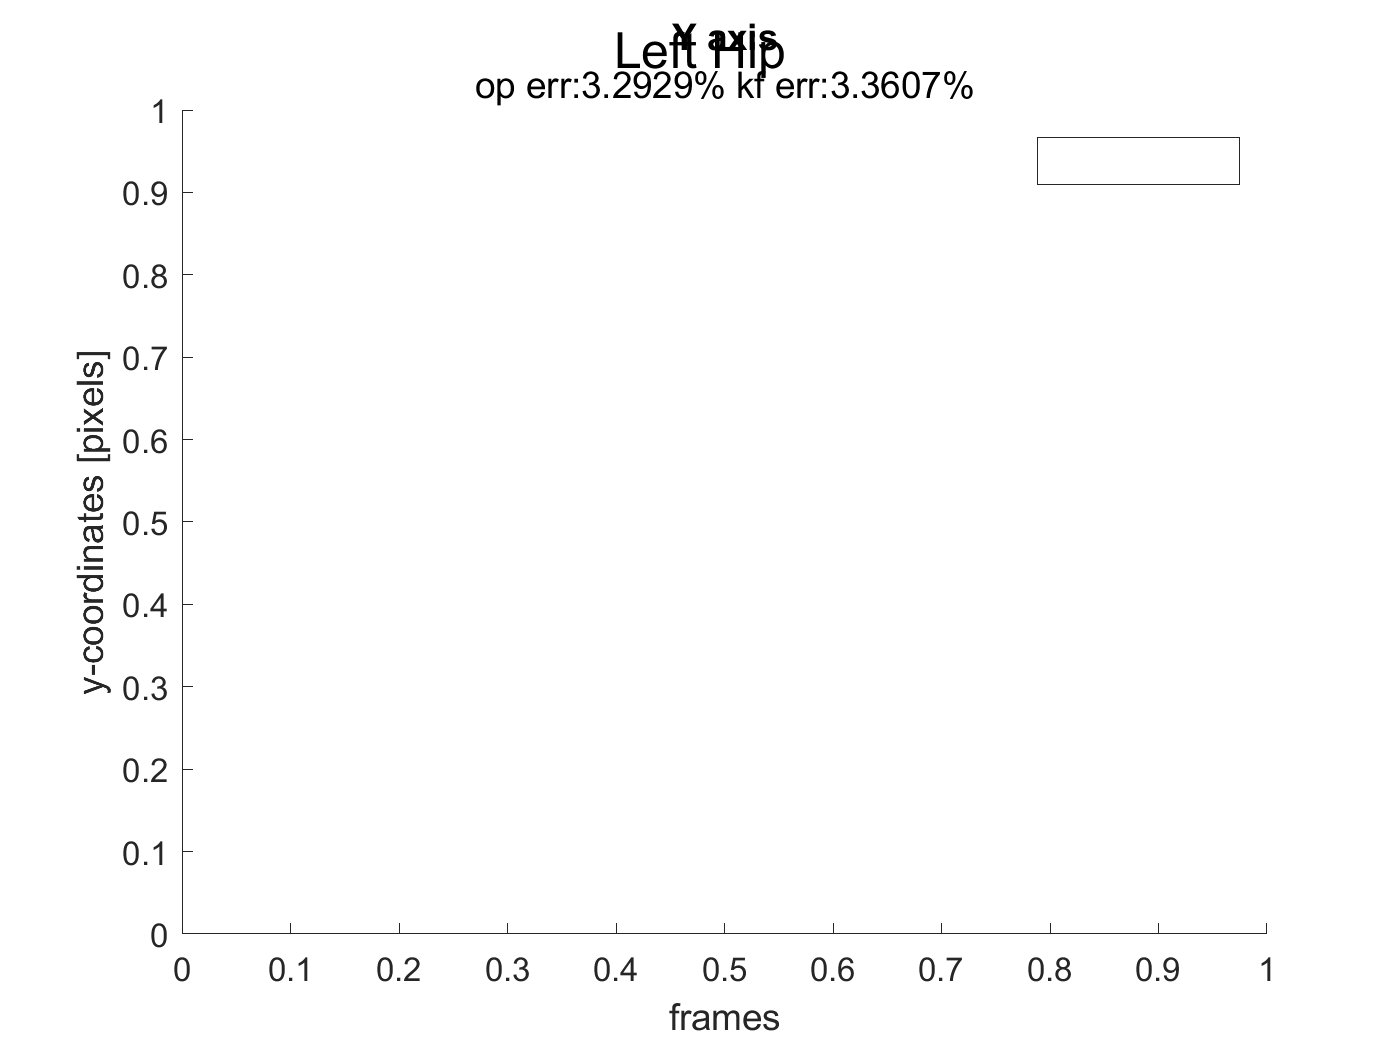

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Left Knee

keypoint_op=[op.l_knee_x op.l_knee_y];
keypoint_mocap=[mocap.LKNE_x mocap.LKNE_y];
keypoint_kf=[kf.l_knee_x kf.l_knee_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Left Knee') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

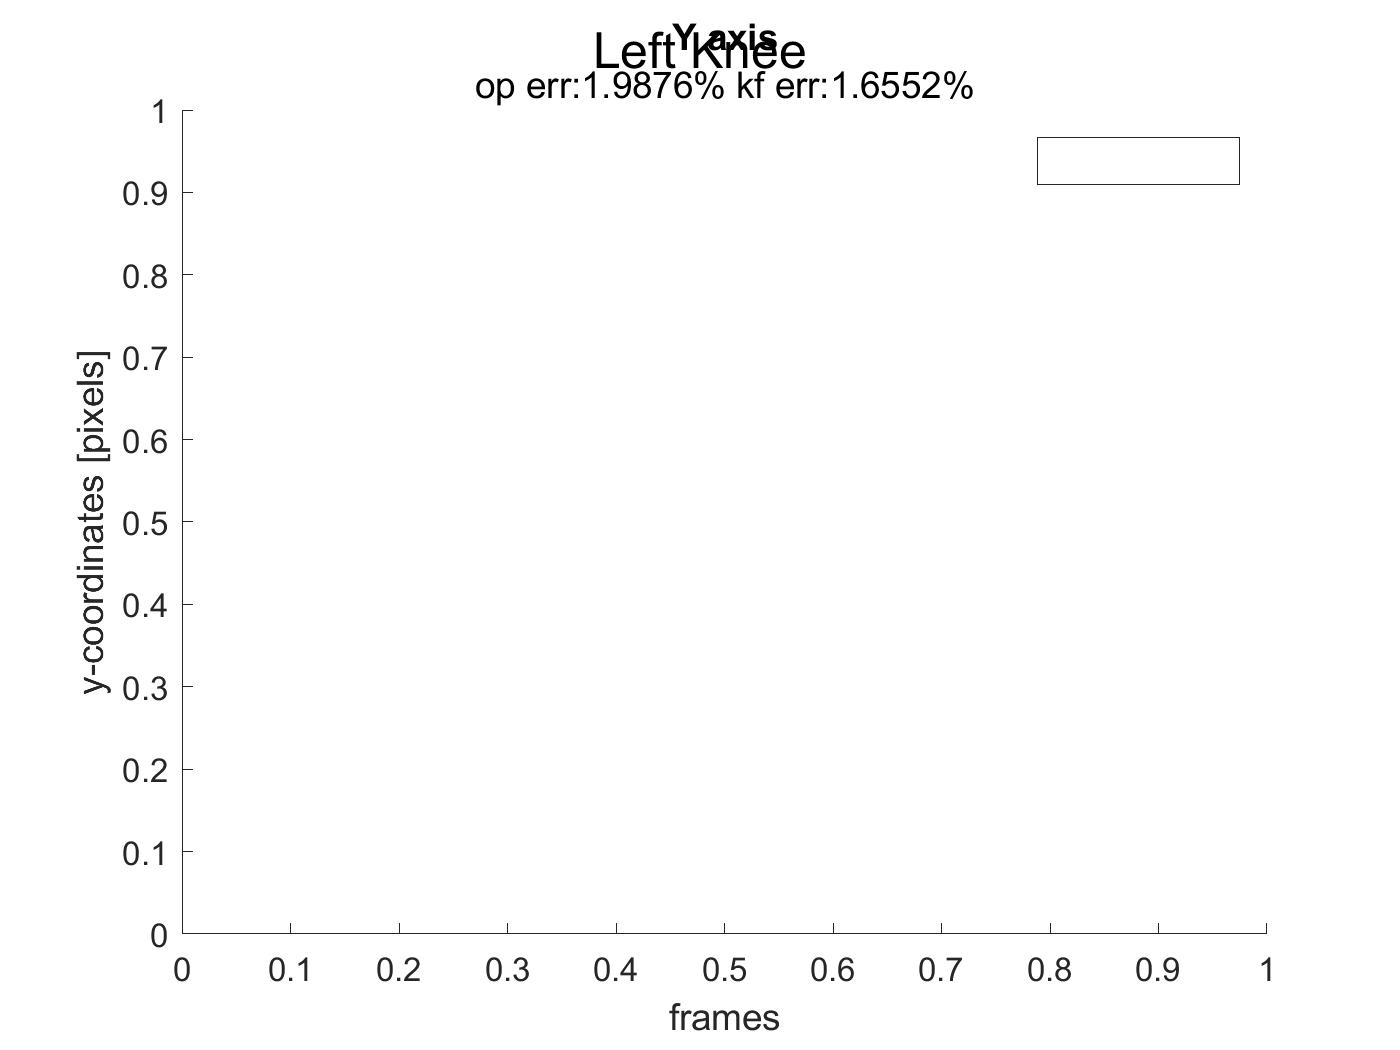

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
title("Y axis")
ylabel('y-coordinates [pixels]')
hold off;

Left ankle

keypoint_op=[op.l_ankle_x op.l_ankle_y];
keypoint_mocap=[mocap.LANK_x mocap.LANK_y];
keypoint_kf=[kf.l_ankle_x kf.l_ankle_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Left Ankle') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

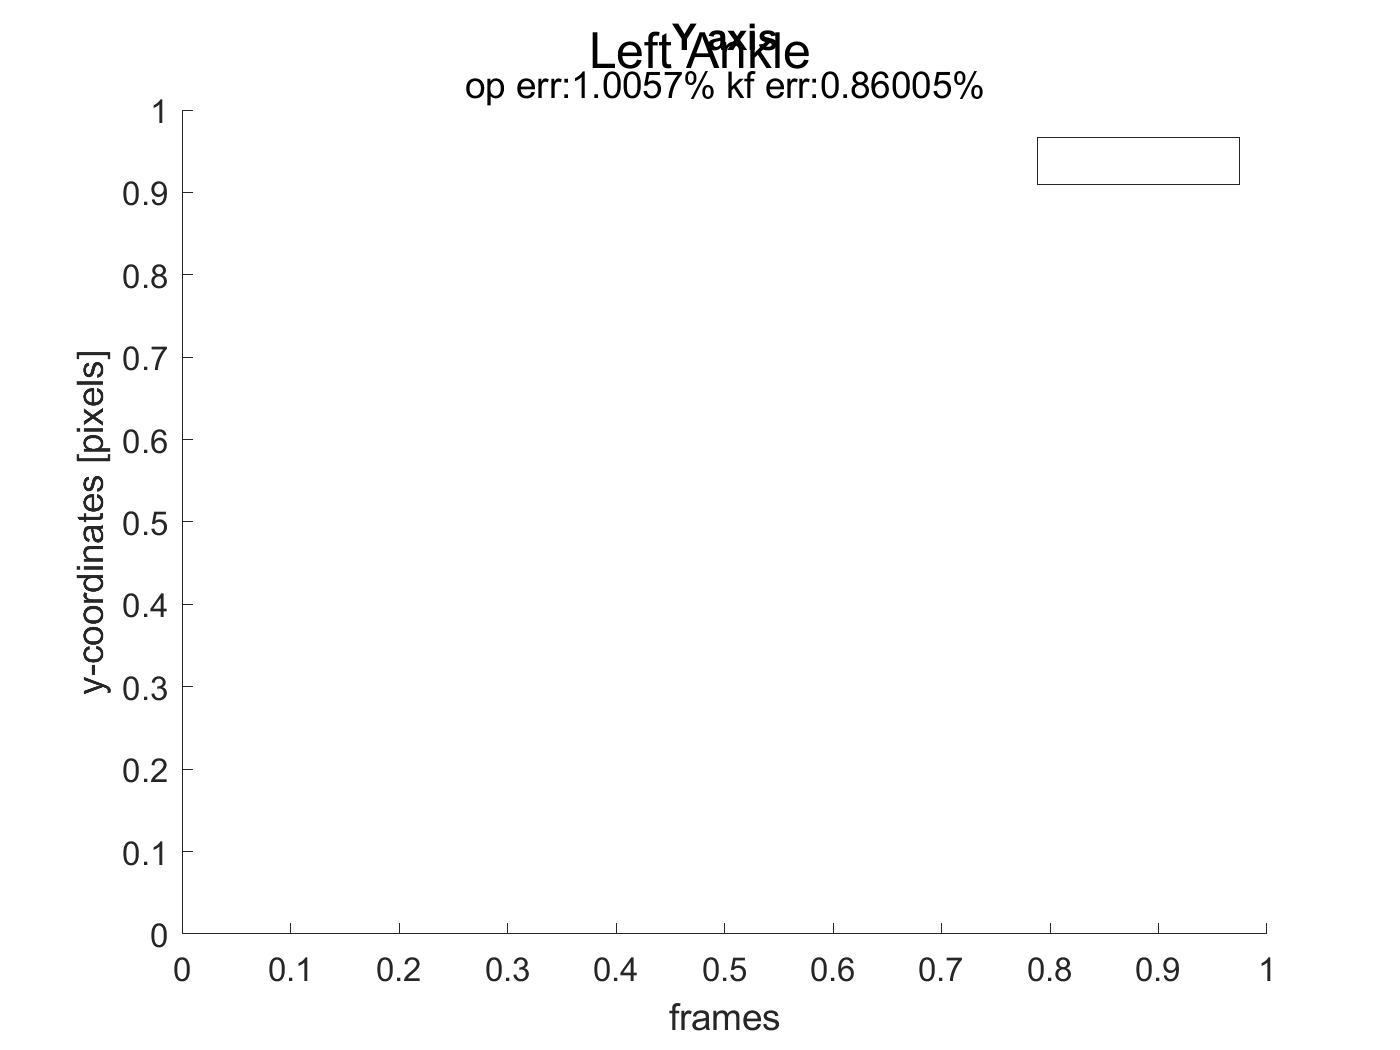

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Left heel

keypoint_op=[op.l_heel_x op.l_heel_y];
keypoint_mocap=[mocap.LHEE_x mocap.LHEE_y];
keypoint_kf=[kf.l_heel_x kf.l_heel_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1)*960;
op_y=keypoint_op(:,2)*540;
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
%figure;
sgtitle('Left Heel') 
%sbplt(1,2,1);
%%plot(op_x,'r-.')
hold on;
%%plot(mocap_x,'b-')
%%plot(start_frame:total_frame, kf_x,'g--')
legend('OpenPose', 'Mocap','KF')

all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

%sbplt(1,2,2);
%%plot(op_y,'r-.')
hold on;
%%plot(mocap_y,'b-')
%%plot(start_frame:total_frame, kf_y,'g--')
legend('OpenPose', 'Mocap','KF')

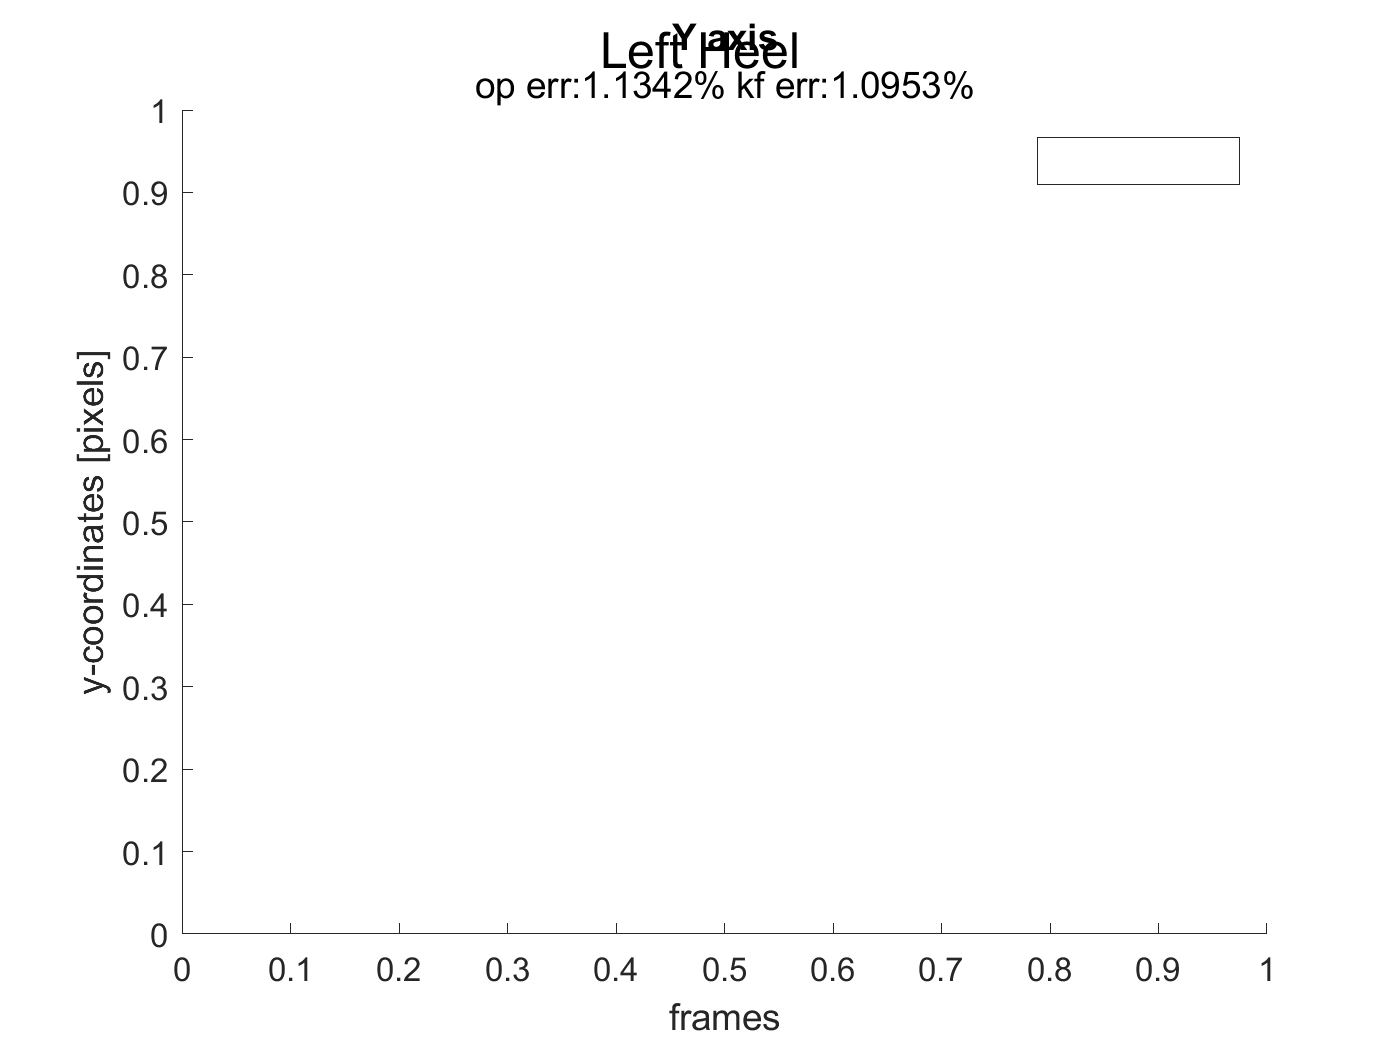

all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

Table

keypoint_names=transpose(["neck" "spine-hip" "r-hip" "r-knee" "r-ankle" "r-heel" "l-hip" "l-knee" "l-ankle" "l-heel"]);

all_errors = table(keypoint_names,errors_x(:,1),errors_x(:,2),errors_y(:,1),errors_y(:,2),'VariableNames',{'keypoint','x-op','x-kf','y-op','y-kf'})

all_errors = 10×5 table
     keypoint       x-op      x-kf       y-op       y-kf  
    ___________    ______    _______    _______    _______

    "neck"         3.8669     3.8217     3.2864     3.1433
    "spine-hip"    4.6584     3.2485     3.3485     3.4452
    "r-hip"        3.7026     2.7537     3.4546     3.5281
    "r-knee"       1.9701     2.0754    0.86524    0.80546
    "r-ankle"      2.1725     1.6401       0.82    0.69129
    "r-heel"       1.5876    0.99213     1.5999      1.561
    "l-hip"        6.4085     4.4798     3.2929     3.3607
    "l-knee"       2.2573     2.0242     1.9876     1.6552
    "l-ankle"      1.5607    0.85703     1.0057    0.86005
    "l-heel"       2.3359     1.7765     1.1342     1.0953
